clc;
clear all;
x=linspace(0,3,31);
C=0.5;
const=4/14;
d1=digits;
digits(4);
for i=1:31
    A(i)=1+2.2*((x(i)-1.5)^2);
    
    if i<6 || i==6
        D(i)=1;
        T(i)=1;
    elseif i>6 && i<17
        D(i)=1-0.366*(x(i)-0.5);
        T(i)=1-0.167*(x(i)-0.5);
    else
        D(i)=0.634-0.3879*(x(i)-1.5);
        T(i)=0.833-0.3507*(x(i)-1.5);
    end
    V(i)=0.59/(D(i)*A(i));
    p(i)=D(i)*T(i);
    U1(i)=D(i)*A(i);
    U2(i)=D(i)*A(i)*V(i);
    U3(i)=D(i)*A(i)*(T(i)*2.5+0.7*(V(i)^2));
    F1(i)=U2(i);
    temp=U2(i)^2/U1(i);
    F2(i)=temp+const*(U3(i)-0.7*temp);
    F3(i)=(1.4*U2(i)*U3(i)/U1(i))-0.28*((U2(i)^3)/(U1(i)^2));
    
    
end
for i=1:31
    del_t(i)=C*(0.1/((T(i)^0.5)+V(i)));
end
t_step=min(del_t);
Net=[transpose(x) transpose(A) transpose(D) transpose(V) transpose(T) transpose(p) transpose(U1) transpose(U2) transpose(U3)];
disp(Net);

         0    5.9500    1.0000    0.0992    1.0000    1.0000    5.9500    0.5900   14.9160
    0.1000    5.3120    1.0000    0.1111    1.0000    1.0000    5.3120    0.5900   13.3259
    0.2000    4.7180    1.0000    0.1251    1.0000    1.0000    4.7180    0.5900   11.8466
    0.3000    4.1680    1.0000    0.1416    1.0000    1.0000    4.1680    0.5900   10.4785
    0.4000    3.6620    1.0000    0.1611    1.0000    1.0000    3.6620    0.5900    9.2215
    0.5000    3.2000    1.0000    0.1844    1.0000    1.0000    3.2000    0.5900    8.0761
    0.6000    2.7820    0.9634    0.2201    0.9833    0.9473    2.6802    0.5900    6.6795
    0.7000    2.4080    0.9268    0.2644    0.9666    0.8958    2.2317    0.5900    5.5022
    0.8000    2.0780    0.8902    0.3189    0.9499    0.8456    1.8498    0.5900    4.5246
    0.9000    1.7920    0.8536    0.3857    0.9332    0.7966    1.5297    0.5900    3.7280
    1.0000    1.5500    0.8170    0.4659    0.9165    0.7488    1.2663    0.5900    3.0939

count=2;
timestep(1)=0;
density(1)=D(16);
massflow(1)=D(16)*V(16)*A(16);
t=0;
while(t<35)
 [dU1_dt,dU2_dt,dU3_dt,F1_p,F2_p,F3_p,D_p,T_p]=predictor(F1,F2,F3,U1,U2,U3,D,t_step,const,A,T);
 [dU1_dtc,dU2_dtc,dU3_dtc]=corrector(F1_p,F2_p,F3_p,D_p,T_p,A);
 dU1_dtavg=(dU1_dt+dU1_dtc)/2;
 dU2_dtavg=(dU2_dt+dU2_dtc)/2;
 dU3_dtavg=(dU3_dt+dU3_dtc)/2;
 for i=2:30
  U1(i)=U1(i)+dU1_dtavg(i)*t_step;
  U2(i)=U2(i)+dU2_dtavg(i)*t_step;
  U3(i)=U3(i)+dU3_dtavg(i)*t_step;
  D(i)=U1(i)/A(i);
  V(i)=U2(i)/U1(i);
  T(i)=0.4*((U3(i)/U1(i))-0.7*V(i)^2);
  p(i)=D(i)*T(i);
  F1(i)=U2(i);
  temp=U2(i)^2/U1(i);
  F2(i)=temp+const*(U3(i)-0.7*temp);
  F3(i)=(1.4*U2(i)*U3(i)/U1(i))-0.28*((U2(i)^3)/(U1(i)^2));
 end
 U2(1)=2*U2(2)-U2(3);
 V(1)=U2(1)/U1(1);
 U3(1)=U1(1)*(T(1)*2.5+0.7*(V(1)^2));
 U1(31)=2*U1(30)-U1(29);
 U2(31)=2*U2(30)-U2(29);
 V(31)=U2(31)/U1(31);
 D(31)=U1(31)/A(31);
 U3(31)=2*U3(30)-U3(29);

 T(31)=0.4*((U3(31)/U1(31))-0.7*V(31)^2);
 F1(1)=U2(1);
 temp1=U2(1)^2/U1(1);
 F2(1)=temp1+const*(U3(1)-0.7*temp1);
 F3(1)=(1.4*U2(1)*U3(1)/U1(1))-0.28*((U2(1)^3)/(U1(1)^2));
 F1(31)=U2(31);
 temp31=U2(31)^2/U1(31);
 F2(31)=temp31+const*(U3(31)-0.7*temp31);
 F3(31)=(1.4*U2(31)*U3(31)/U1(31))-0.28*((U2(31)^3)/(U1(31)^2));
 Net=[transpose(x) transpose(A) transpose(D) transpose(V) transpose(T) transpose(p) transpose(U1) transpose(U2) transpose(U3)];
 disp(Net);
 t=t+t_step;
 timestep(count)=t;
 density(count)=D(16);

 massflow(count)=D(16)*V(16)*A(16);
 count=count+1;
end

         0    5.9500    1.0000    0.0990    1.0000    1.0000    5.9500    0.5888   14.9158
    0.1000    5.3120    1.0000    0.1108    1.0000    1.0000    5.3122    0.5885   13.3262
    0.2000    4.7180    1.0000    0.1247    1.0000    1.0000    4.7180    0.5882   11.8464
    0.3000    4.1680    1.0000    0.1410    1.0000    1.0000    4.1680    0.5879   10.4782
    0.4000    3.6620    1.0000    0.1604    1.0000    1.0000    3.6620    0.5875    9.2211
    0.5000    3.2000    0.9994    0.1865    0.9998    0.9992    3.1980    0.5963    8.0715
    0.6000    2.7820    0.9636    0.2263    0.9834    0.9476    2.6806    0.6065    6.6866
    0.7000    2.4080    0.9270    0.2698    0.9667    0.8961    2.2322    0.6022    5.5084
    0.8000    2.0780    0.8904    0.3232    0.9500    0.8459    1.8502    0.5981    4.5297
    0.9000    1.7920    0.8538    0.3884    0.9333    0.7969    1.5300    0.5942    3.7315
    1.0000    1.5500    0.8172    0.4663    0.9166    0.7490    1.2667    0.5907    3.0953

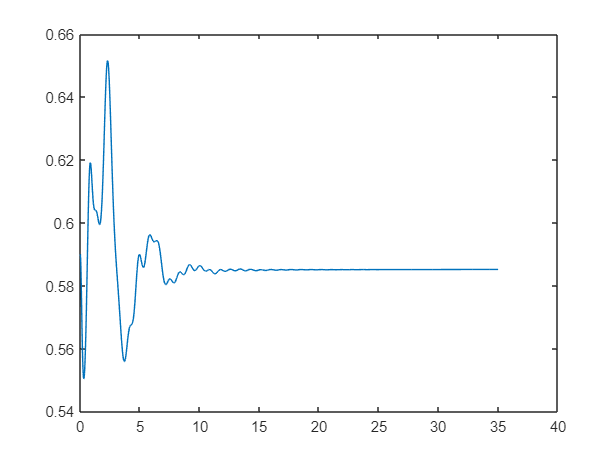


plot(timestep,massflow);

 function [dU1_dt,dU2_dt,dU3_dt,F1_p,F2_p,F3_p,D_p,T_p]=predictor(F1,F2,F3,U1,U2,U3,D,t_step,const,A,T)
   F1_p(1)=F1(1);
   F2_p(1)=F2(1);
   F3_p(1)=F3(1);
   D_p(1)=D(1);
   T_p(1)=T(1);
   for i=2:30
       dU1_dt(i)=-(F1(i+1)-F1(i))/0.1;
       dU2_dt(i)=-((F2(i+1)-F2(i))/0.1)+(1/1.4)*D(i)*T(i)*((A(i+1)-A(i))/0.1);
       dU3_dt(i)=-(F3(i+1)-F3(i))/0.1;
       U1_p(i)=U1(i)+dU1_dt(i)*t_step;
       U2_p(i)=U2(i)+dU2_dt(i)*t_step;
       U3_p(i)=U3(i)+dU3_dt(i)*t_step;
       F1_p(i)=U2_p(i);
       temp1=U2_p(i)^2/U1_p(i);
       F2_p(i)=temp1+const*(U3_p(i)-0.7*temp1);
       F3_p(i)=(1.4*U2_p(i)*U3_p(i)/U1_p(i))-0.28*((U2_p(i)^3)/(U1_p(i)^2));
       D_p(i)=U1_p(i)/A(i);
       T_p(i)=0.4*((U3_p(i)/U1_p(i))-0.7*(U2_p(i)/U1_p(i))^2);
   end
   F1_p(31)=F1(31);
   F2_p(31)=F2(31);
   F3_p(31)=F3(31);
   D_p(31)=D(31);
   T_p(31)=T(31);
   
end
function [dU1_dtc,dU2_dtc,dU3_dtc]=corrector(F1_p,F2_p,F3_p,D_p,T_p,A)
   for i=2:30
       dU1_dtc(i)=-(F1_p(i)-F1_p(i-1))/0.1;
       dU2_dtc(i)=-((F2_p(i)-F2_p(i-1))/0.1)+(1/1.4)*D_p(i)*T_p(i)*((A(i)-A(i-1))/0.1);
       dU3_dtc(i)=-(F3_p(i)-F3_p(i-1))/0.1;
   end
end



    



